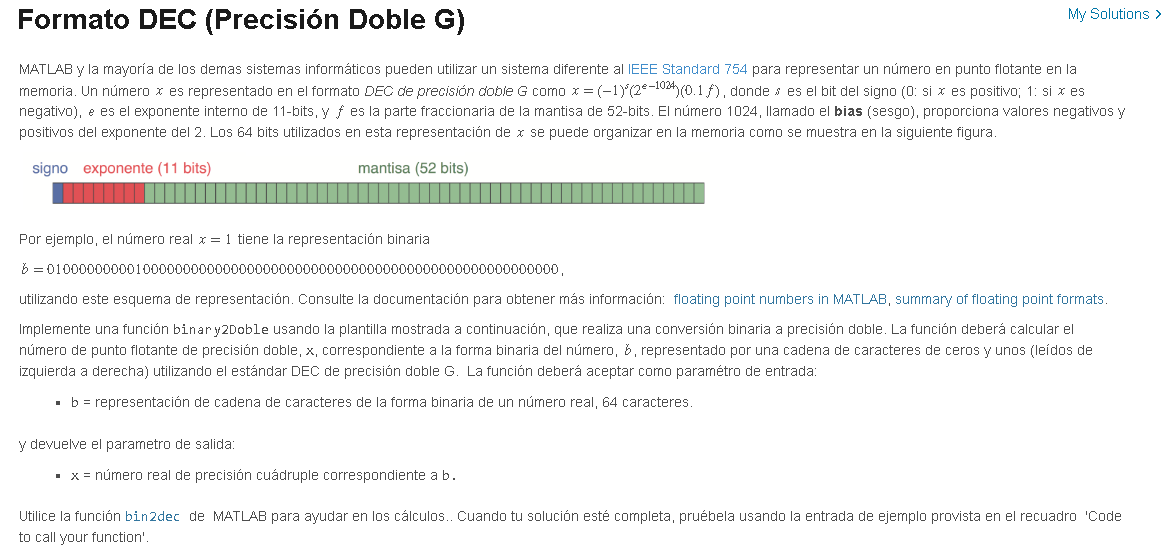

b='0100000000010000000000000000000000000000000000000000000000000000';
x=binary2Doble(b)

x =      1


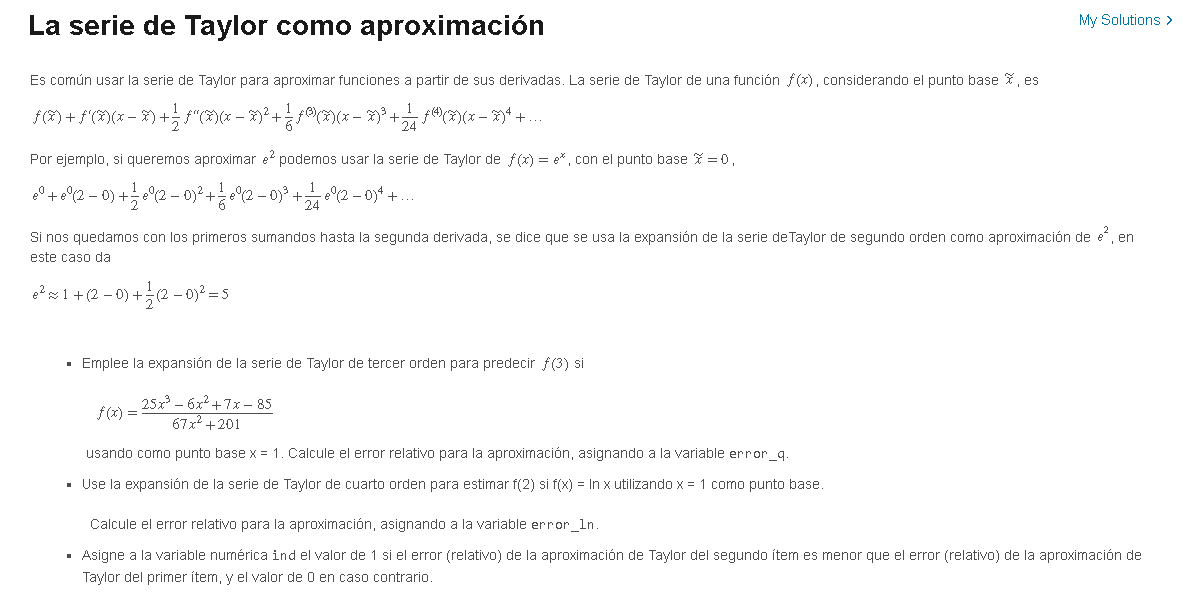

format long 
syms x

f1 = (25*(x^3)-6*(x^{2})+7*x-85)/(67*x^{2}+201)

$$f1 = \frac{25\,x^{3}-6\,x^{2}+7\,x-85}{67\,x^{2}+201}$$

r1 = double(subs(f1,{x},{1}))

r1 =   -0.220149253731343


coef = f1;

for i = 1:3
    coef = diff(coef);
    r1 = r1 + subs(coef,1) * ((x-1)^{i}) / factorial(i);
end

r1

$$r1 = \frac{199\,x}{536}+\frac{17\,{\left(x-1\right)}^{2}}{134}-\frac{135\,{\left(x-1\right)}^{3}}{2144}-\frac{317}{536}$$


f2 = log(x);
r2 = double(subs(f2,x,1));
coef = f2;
for i = 1:4
    coef = diff(coef);
    r2 = r2 + subs(coef,1) * ((x-1)^{i}) / factorial(i);
end

r2

$$r2 = x-\frac{{\left(x-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{3}}{3}-\frac{{\left(x-1\right)}^{4}}{4}-1$$

error_q = abs(double(subs(f1,3)) - double(subs(r1,3))) / abs(double(subs(f1,3)))

error_q =    0.240574506283662


error_ln = abs(double(subs(f2,2))-double(subs(r2,2)))/abs(double(subs(f2,2)))

error_ln =    0.158427892814771



ind=0;

if(error_ln<error_q) 
    ind=1;
end

ind

ind =      1


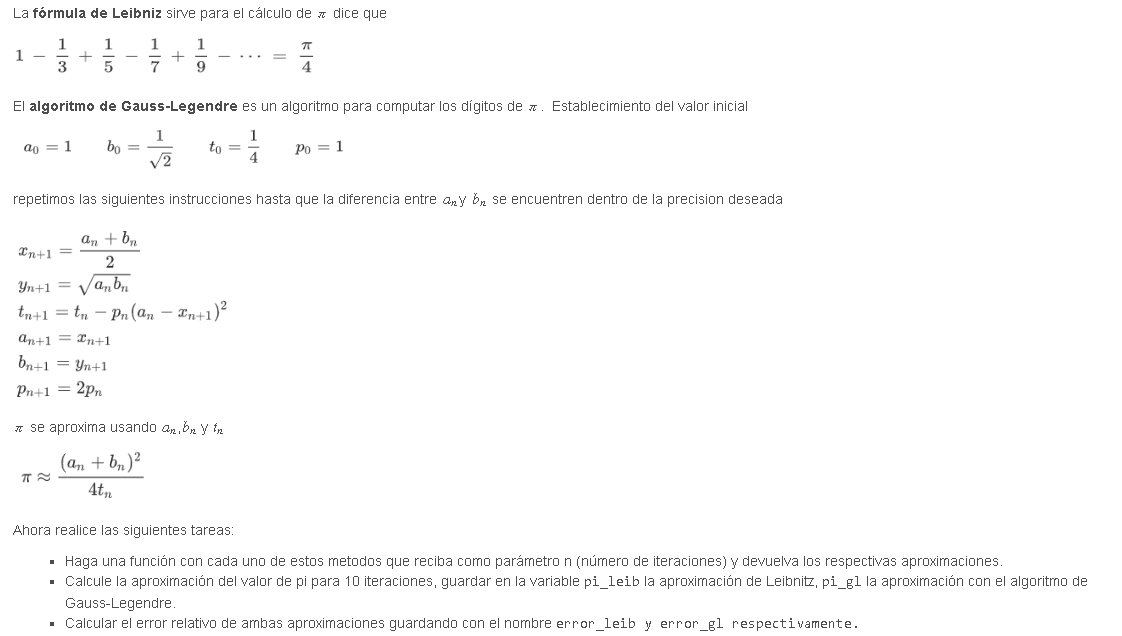

pi_leib = leibniz_pi(10)

pi_leib =    3.041839618929403



error_leib = abs(pi_leib-pi)/pi

error_leib =    0.031752377109236



pi_gl = gauss_legendre_pi(10)

pi_gl =    3.141592653589794



error_gl = abs(pi_gl-pi)/pi

error_gl =      2.827159716856459e-16


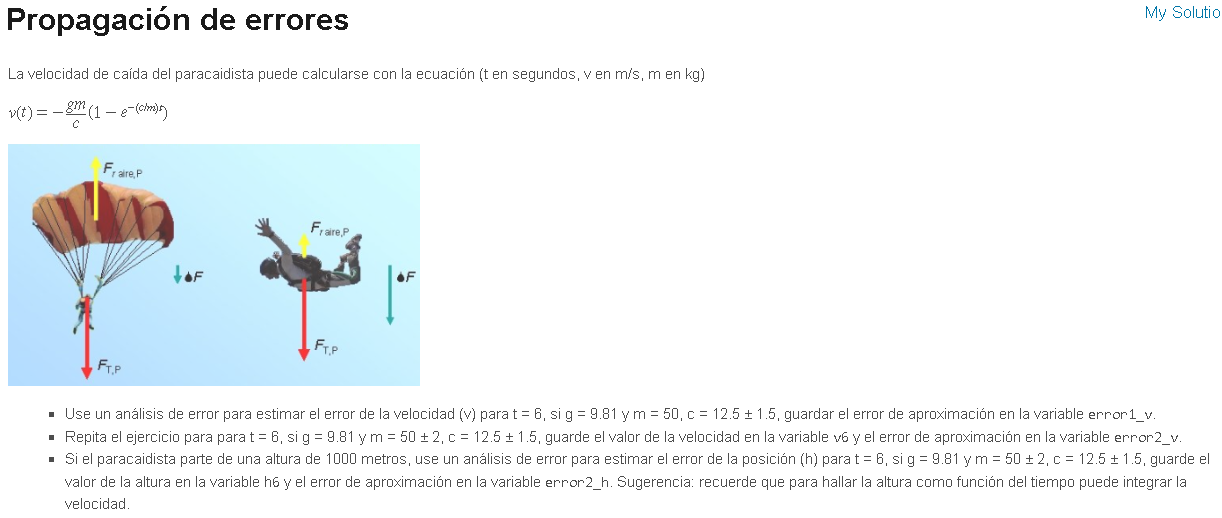

syms g m c t
v= (-g*m/c)*(1-exp(-c*t/m))

$$v = \frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c}$$

%////////////////////////
error_c=1.5;
dv_dc= diff(v,c);
dv = abs(dv_dc)*error_c;
error1_v= double( subs(dv,{t,g,m,c},{6,9.81,50,12.5}))

error1_v =    2.082111754732684



%////////////////////////
error_m= 2

error_m =      2


error_c=1.5

error_c =    1.500000000000000



dv_dm= diff(v,m)

$$dv\_dm = \frac{g\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c}+\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{m}$$

dv_dc= diff(v,c)

$$dv\_dc = -\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{c}-\frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c^{2}}$$

dv = abs(dv_dm)*error_m + abs(dv_dc)*error_c

$$dv = 2\,\left|\frac{g\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c}+\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{m}\right|+\frac{3\,\left|\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{c}+\frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c^{2}}\right|}{2}$$


error2_v = double( subs(dv,{t,g,m,c},{6,9.81,50,12.5}))

error2_v =    2.776149006310245


v6 = double(subs(v,{t,g,m,c},{6,9.81,50,12.5}))

v6 =  -30.484372515775615



%/////////////////7
h0= 1000;

% h-h0 = F1-F2
h= int(v)-subs(int(v),0)+h0

$$h = \frac{g\,m^{2}}{c^{2}}-\frac{g\,m\,\left(m\,{\mathrm{e}}^{-\frac{c\,t}{m}}+c\,t\right)}{c^{2}}+1000$$



h6 = double( subs(h,{t,g,m,c},{6,9.81,50,12.5}))

h6 =      8.864974900631024e+02



% t = 6, si g = 9.81 y m = 50 ± 2, c = 12.5 ± 1.5
error_m = 2;
error_c=1.5;

dh_dm = diff(h,m);
dh_dc = diff(h,c);

dh= abs(dh_dm)*error_m + abs(dh_dc)*error_c

$$dh = \begin{array}{l} 2\,\left|\frac{g\,\sigma_{1}}{c^{2}}-\frac{2\,g\,m}{c^{2}}+\frac{g\,m\,\left(\sigma_{2}+\frac{c\,t\,\sigma_{2}}{m}\right)}{c^{2}}\right|+\frac{3\,\left|\frac{2\,g\,m^{2}}{c^{3}}+\frac{g\,m\,\left(t-t\,\sigma_{2}\right)}{c^{2}}-\frac{2\,g\,m\,\sigma_{1}}{c^{3}}\right|}{2}\\ \mathrm{where}\\ \sigma_{1}=m\,\sigma_{2}+c\,t\\ \sigma_{2}={\mathrm{e}}^{-\frac{c\,t}{m}} \end{array}$$


error2_h = double( subs(dh,{t,g,m,c},{6,9.81,50,12.5}) )

error2_h =    7.055805564662625


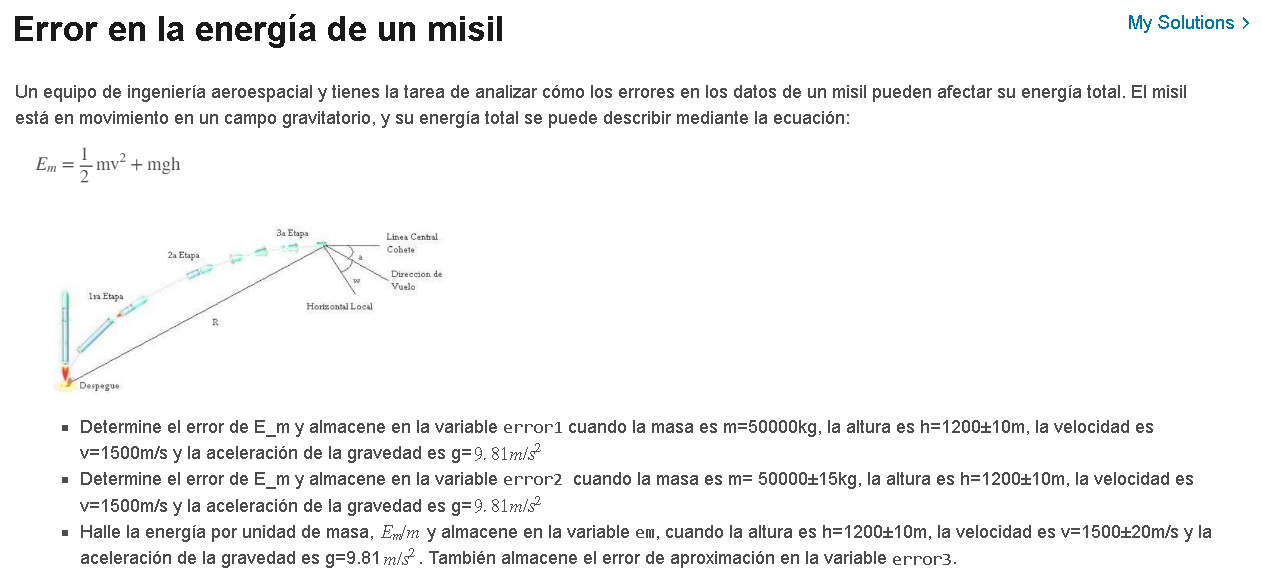

syms m v g h

Em = m*(v^{2})/2 + m*g*h;

% CASO 1
m1=50000;
h1=1200;
error_h1 = 10;
v1 = 1500;
g1= 9.81;

dEm = abs(diff(Em,h))*error_h1

$$dEm = 10\,\left|g\,m\right|$$

error1 = double( subs(dEm,{m,v,g,h},{m1,v1,g1,h1}))

error1 =      4905000



% CASO 2
m2=50000;
error_m2=15;

h2=1200;
error_h2=10;

v2 = 1500;
g2=9.81;

dEm = abs(diff(Em,m))*error_m2 + abs(diff(Em,h))*error_h2;

error2= double( subs(dEm,{m,v,g,h},{m2,v2,g2,h2}))

error2 =     21956580



% CASO 3
h3 =1200;
error_h3 = 10;

v3 = 1500;
error_v3=20;

g3=9.81;
fem = simplifyFraction(Em/m);
em = double(subs(fem,{v,g,h},{v3,g3,h3}))

em =      1136772



dem= abs(diff(fem,h))*error_h3 + abs(diff(fem,v))*error_v3;

error3= double( subs(dem,{v,g,h},{v3,g3,h3}))

error3 =      3.009810000000000e+04


function x = binary2Doble(b)
% Extraiga los bits de signo, exponente y mantisa de la cadena.
s = b(1);
e = b(2:12);
m = b(13:end);

% Convierte los bits a valores decimales.
signo= (-1)^(bin2dec(s));
exp = bin2dec(e)-1024;
frac= strcat('1',m);
val = bin2dec(frac)*2^(-53);

% Convierte a un número real usando el DEC Standard.
x=signo*val*(2^exp);
end

function pi_approx = gauss_legendre_pi(n)
% n: número de iteraciones
% pi_approx: valor aproximado de pi

    % complete aquí
    ans = 0;
    a = 1;
    b= 1/sqrt(2);
    t= 1/4;
    p=1;
    
    for i=0:n-1
        x= (a+b)/2;
        y= sqrt(a*b);
        t= t-p*((a-x)^2);
        a=x;
        b=y;
        p=2*p;
    end
    
    pi_approx = ( (a+b)^2 )/(4*t);
end

function pi_ap = leibniz_pi(n)
% n: número de iteraciones
% pi_ap: valor aproximado de pi

    % complete aquí
    tmp = 0;
    for i= 0:n-1
        tmp = tmp + ((-1)^i)/(2*i+1);
    end
    
    pi_ap = 4*tmp;
    
end
